% Import instron CSV data 
if 1 % Wrap in an "if" so the warnings all print at the end
    tab_instron_1 = readtable("StepStrainSweepPressure2_1.csv");
    tab_instron_2 = readtable("StepStrainSweepPressure2_2.csv");
    tab_instron_3 = readtable("StepStrainSweepPressure2_3.csv");
end

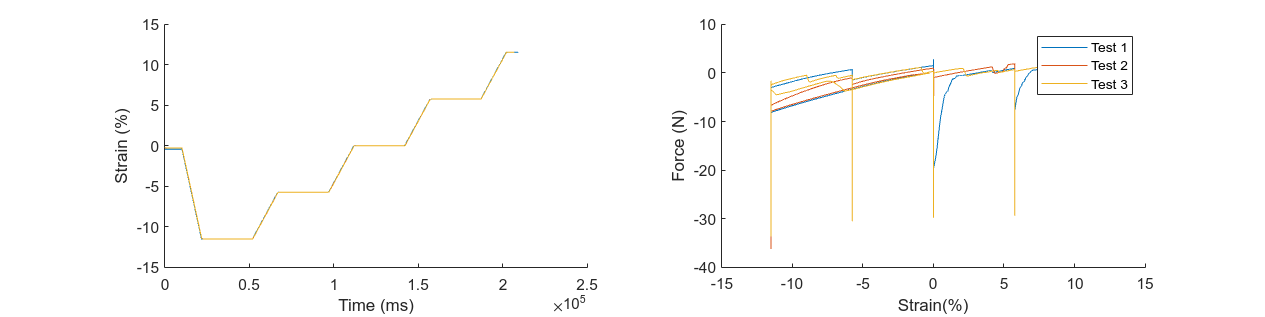

instron_data_tables = {tab_instron_1, tab_instron_2, tab_instron_3};

fig = figure();
set(fig, "Position", [0, 0, 1600, 400])
subplot(1, 2, 1);
hold on;
for i = 1 : length(instron_data_tables)
    plot(instron_data_tables{i}.Time, instron_data_tables{i}.TensileStrain_Displacement_);
end
xlabel("Time (ms)")
ylabel("Strain (%)")

subplot(1, 2, 2);
hold on
for i = 1 : length(instron_data_tables)
    plot(instron_data_tables{i}.TensileStrain_Displacement_, instron_data_tables{i}.Force);
end
xlabel("Strain(%)");
ylabel("Force (N)")
legend(["Test 1", "Test 2", "Test 3"]);

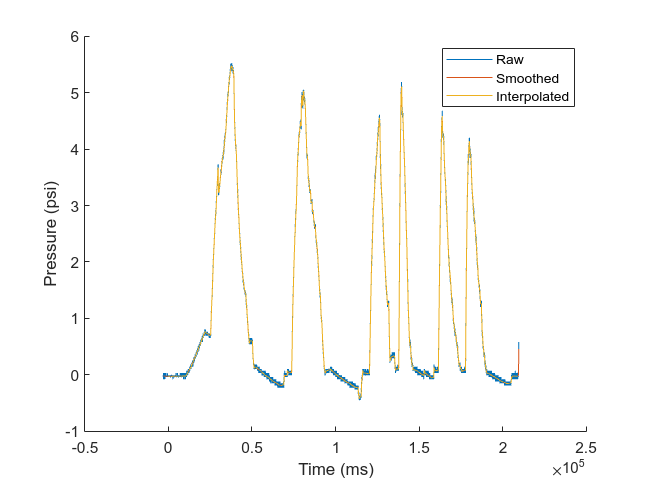

tab_pressures_1 = readtable("07-08-2023-10-49-23.txt");
tab_pressures_1.Time = tab_pressures_1.Time - 0.3 * 1e4; % Manual time alignment correction

% Smooth the pressures with a moving average
pressure_1_smoothed = smoothdata(tab_pressures_1.Pressure, "gaussian", 200);

% Interpolate pressures at the timestamps of the instron logs
[pressure_1_times_unique, i_times] = unique(tab_pressures_1.Time);
pressure_1_interp = interp1(pressure_1_times_unique, pressure_1_smoothed(i_times), tab_instron_1.Time);

fig = figure();
hold on;
plot(tab_pressures_1.Time, tab_pressures_1.Pressure);
plot(tab_pressures_1.Time, pressure_1_smoothed);
plot(instron_data_1.Time, pressure_1_interp);

xlabel("Time (ms)")
ylabel("Pressure (psi)");
legend(["Raw", "Smoothed", "Interpolated"])

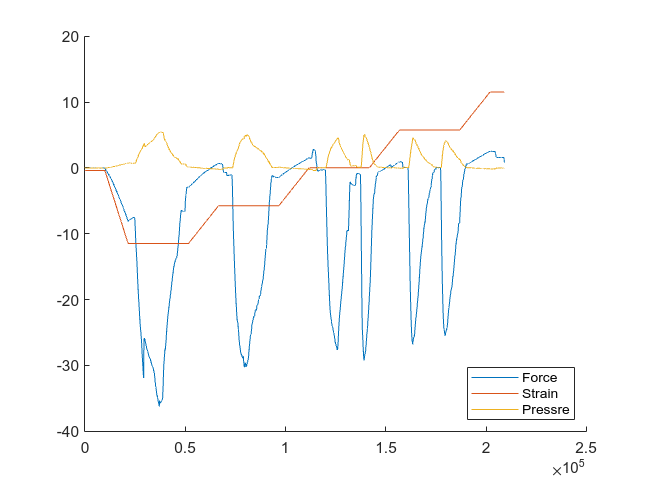

figure()
hold on
plot(tab_instron_1.Time, tab_instron_1.Force);
plot(tab_instron_1.Time, tab_instron_1.TensileStrain_Displacement_);
plot(tab_instron_1.Time, pressure_1_interp);
legend("Force", "Strain", "Pressre", "Location", "southeast");

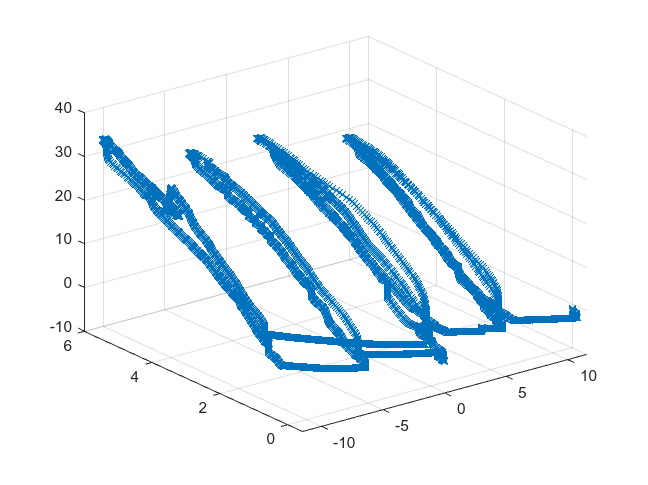

figure()
scatter3(tab_instron_1.TensileStrain_Displacement_, pressure_1_interp, -tab_instron_1.Force, 'x');